## "Database"

addpath('functions');

% Parameters
commonSize = [400, 300];
folderPath = 'images/DB1';
threshold = 1.0;  % Threshold for variance explanation

% Load and preprocess images
[dataMatrix, imageFiles] = load_and_preprocess_images(folderPath, commonSize);

% Perform PCA
[score, meanFace, numEigenfaces, eigenfaces, numComponentsRequired] = perform_pca(dataMatrix, threshold);

% Display number of components required
fprintf('Number of principal components needed: %d\n', numComponentsRequired);

Number of principal components needed: 15


## Daniels input

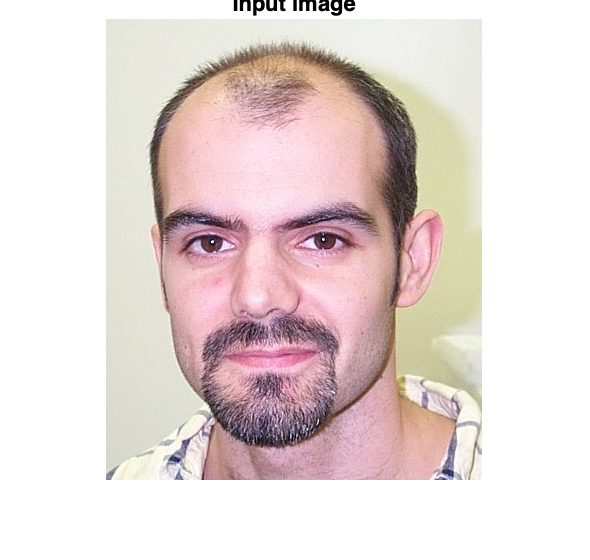

addpath('functions');

% DB1
inputImage = imread('images/DB1/db1_08.jpg');

% DB2
% inputImage = imread('images/DB2/bl_01.jpg');

imshow(inputImage);
title('Input image');

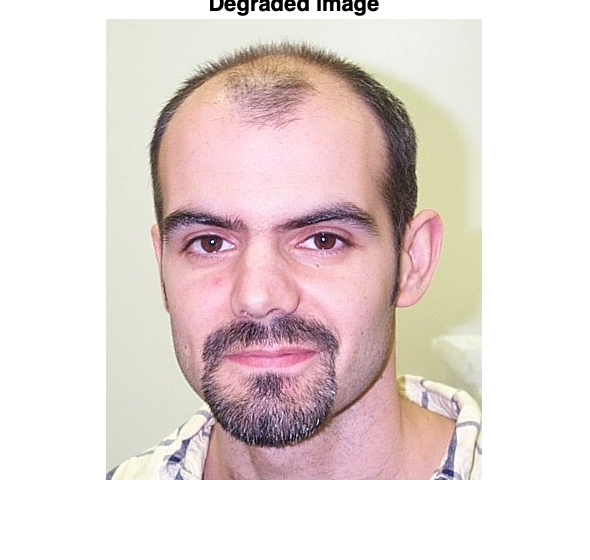

% editedImage = degrade_img(inputImage);
editedImage = inputImage;

imshow(editedImage);
title('Degraded image');

## Compensation

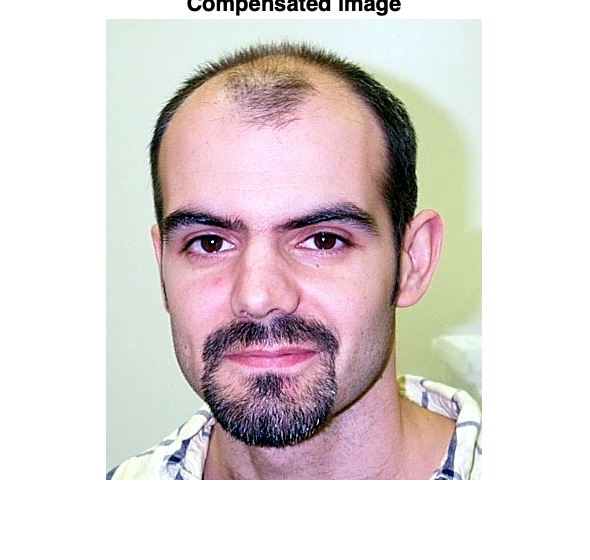

% editedImage = tone_compensation(editedImage);
% imshow(editedImage);
% title('Compensated image');

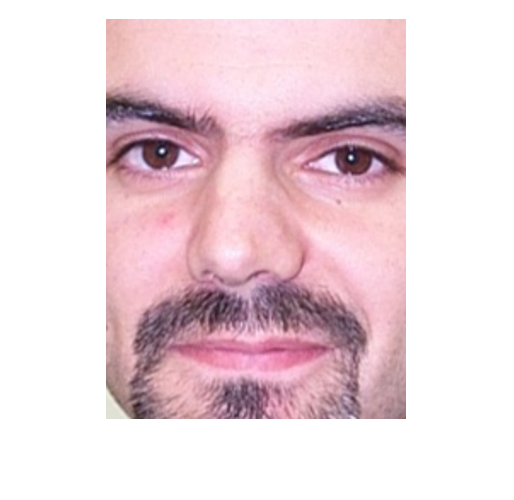

% Call the face_detection function
[eyeCoordinates, mouthCoordinate] = face_detection(editedImage);

% Compensate for rotation
[rotatedImage, rotatedEyeCoordinates, rotatedMouthCoordinate] = rotation_compensation(editedImage, eyeCoordinates, mouthCoordinate);

% Crop the image
croppedImage = crop_img(rotatedImage, rotatedEyeCoordinates, rotatedMouthCoordinate);
imshow(croppedImage)

## Project query image onto eigenfaces

The query image matches with image #8 in the training set.


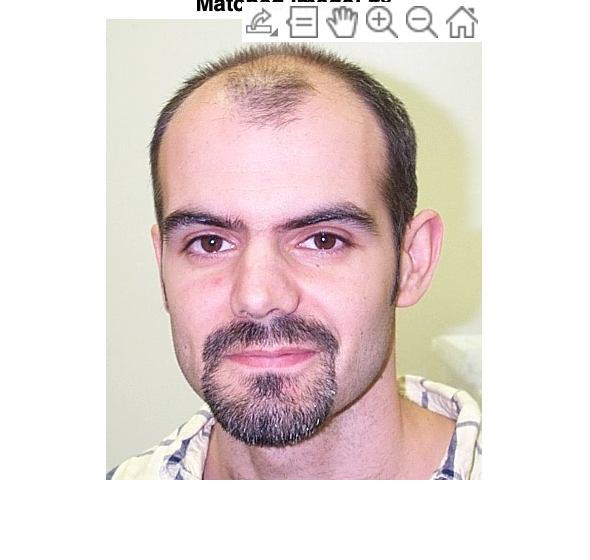

queryWeights = project_onto_eigenfaces(croppedImage, eigenfaces, meanFace);

% Recognize the face
recognize_face(queryWeights, score, folderPath, imageFiles, numEigenfaces);